close all
clearvars
clc

filename1 ="D:\RFFI-based-on-CVCNN\datasets\ORACLE\neu_m044q5210\KRI-16Devices-RawData\2ft\WiFi_air_X310_3123D7B_2ft_run1.sigmf-data";
filename2 ="D:\RFFI-based-on-CVCNN\datasets\ORACLE\neu_m044q5210\KRI-16Devices-RawData\2ft\WiFi_air_X310_3123D7B_2ft_run2.sigmf-data";
filename3="D:\RFFI-based-on-CVCNN\datasets\ORACLE\neu_m044q5210\KRI-16Devices-RawData\2ft\WiFi_air_X310_3123D7D_2ft_run1.sigmf-data";
filename4 ="D:\RFFI-based-on-CVCNN\datasets\ORACLE\neu_m044q5210\KRI-16Devices-RawData\62ft\WiFi_air_X310_3123D7B_62ft_run1.sigmf-data";
filename5="D:\RFFI-based-on-CVCNN\datasets\ORACLE\neu_m044q523j\KRI-16IQImbalances-DemodulatedData\Demod_WiFi_cable_X310_3123D76_IQ#1_run1.sigmf-data";

fid = fopen(filename1, 'r');
sr = 5e6;%%采样率
% fseek(fid, 4096, 'bof');
ref = fread(fid,'float64');                           
% ref = fread(fid, (sr*0.1)*2,'complex64');%%读1s的数据
fclose(fid);
ref = ref(1:2:end)+1j*ref(2:2:end); 
length(ref)

ans = 2196960

c1_2ft_run1=ref(1:128);

sigreal=real(ref);
sigimag=imag(ref)

sigimag =     0.7990
   -1.3440
    0.9960
   -0.4424
   -0.6874
    1.3798
    0.7808
   -0.8435
   -0.4352
   -0.6970


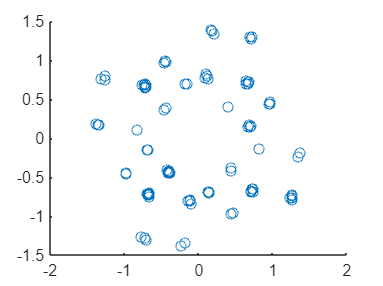

beginpoint=1;
sigreal=sigreal(beginpoint:beginpoint+100);
sigimag=sigimag(beginpoint:beginpoint+100);
% plot(sigreal);
% 
% plot(sigimag);
scatter(sigreal,sigimag)

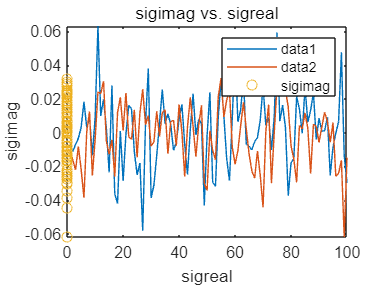

% 创建 sigreal 和 sigimag 的 scatter
s = scatter(sigreal,sigimag,"DisplayName","sigimag");

% 添加 xlabel, ylabel, title 和 legend
xlabel("sigreal")
ylabel("sigimag")
title("sigimag vs. sigreal")
legend